## Rogelio Torres

## Alejandro Bermúdez

## Moises Aguirre

# Primer Proyecto Algorítmos Numéricos por Computadora

**Instrucciones: **

El objetivo de este proyecto es observar los errores que presentan diferentes [fórmulas de derivación numérica](https://itam.instructure.com/courses/3332/files/466218?wrap=1)[  descargar](https://itam.instructure.com/courses/3332/files/466218/download?download_frd=1). Deben explorarse aproximaciones centradas, hacia adelante y hacia atrás; de la primera y segunda derivada; O(h)O(h) y O(h2)O(h2). ¿Qué fórmulas presentan menos errores? ¿Cómo dependen de *h*?  ¿El error siempre disminuye si *h* se hace más pequeño? ¿Qué otro factor influye en el error? Deben tener como parámetros de entrada la función *f* a derivar y el punto *x*.  Para obtener el valor exacto de la derivada deben calcularla simbólicamente. Ver la sección *Total numerical error* del libro de texto.

**Proyecto:**

Para comenzar, declaramos una función simbólica f(x) que utilizaremos como base para nuestras pruebas y un punto p en el que evaluaremos . 

Es importante notar que f(x) es una función simbólica para poder evaluarla y calcular su derivada. 

syms f(x)
f(x)=x^2+6*x-1  

$$f(x) = x^{2}+6\,x-1$$

punto=10

punto = 10

De esta función calcularemos la derivada y segunda derivada usando el método diff(), y usaremos el valor como marco de referencia. 

derivada_referencia=diff(f);
segunda_derivada_referencia=diff(derivada_referencia)

$$segunda\_derivada\_referencia(x) = 2$$

Ahora evaluaremos la derivada en el punto

derivada_evaluada=vpa(derivada_referencia(punto))

$$derivada\_evaluada = 26.0$$

segunda_derivada_evaluada=vpa(segunda_derivada_referencia(punto))

$$segunda\_derivada\_evaluada = 2.0$$

A continuación realizaremos un ciclo "while" en el que calcularemos las derivadas usando las siguientes fórmulas: 

Fórmula "Forward difference": 𝑓′(𝑥)=(𝑓(𝑥+ℎ)−𝑓(𝑥))/ℎ

Fórmula "Backward difference": 𝑓′(𝑥)=(𝑓(𝑥)−𝑓(𝑥−ℎ))/ℎ

Fórmula "Central difference": 𝑓′(𝑥)=(𝑓(𝑥+ℎ)−𝑓(𝑥−ℎ))/2ℎ

Además, dentro de este ciclo también calcularemos el error de cada fórmula utilizando una resta. 

Finalmente, es importante aclarar que utilizaremos un valor de h que comenzará en 1 y disminuirá 10 veces en cada iteración del ciclo. 

Es importante aclarar que el ciclo tendrá un total de 10 iteraciones. 

i=1; 
while(i<=10)
    %Cálculo del valor h que disminuye en cada ciclo
    h(i) = 1/(10^(i-1));
    
% Primera Derivada
    %Cálculo de los valores en los que se evaluarán las derivadas
    f_x=f(punto);
    f_x_mas_h=f(punto+h(i));
    f_x_menos_h=f(punto-h(i));
    
    %Calculamos derivada hacia adelante
    derivada_adelante=vpa((f_x_mas_h-f_x)/h(i));
    %Calculamos derivada hacia atrás
    derivada_atras=vpa((-f_x_menos_h+f_x)/h(i));
    %Cálculo derivada central
    derivada_central=(f_x_mas_h-f_x_menos_h)/(2*h(i));
    
    %Ahora calculamos el error dentro del ciclo y almacenamos el resultado
    %en un vector con el mismo numero de iteraciones
    error_adelante(i)=abs(derivada_adelante-derivada_evaluada);
    error_atras(i)=abs(derivada_atras-derivada_evaluada);
    error_central(i)=abs(derivada_central-derivada_evaluada);
    
%Segunda derivada
    %Primero calculamos algunos valores a usar
    s_f_x=derivada_evaluada;
    s_f_x_mas_h=derivada_referencia(punto+h(i));
    s_f_x_menos_h=derivada_referencia(punto-h(i));
    
    %Calculamos la segunda derivada hacia adelante
    s_derivada_adelante=(s_f_x_mas_h-s_f_x)/h(i);
    %Calculamos la segunda derivada hacia atrás
    s_derivada_atras=(s_f_x-s_f_x_menos_h)/h(i);
    %Cálculamos la segunda derivada central
    s_derivada_central=(s_f_x_mas_h-s_f_x_menos_h)/(2*h(i));
    
    %Calculamos el error
    s_error_adelante(i)=abs(s_derivada_adelante-segunda_derivada_evaluada);
    s_error_atras(i)=abs(s_derivada_atras-segunda_derivada_evaluada);
    s_error_central(i)=abs(s_derivada_central-segunda_derivada_evaluada);
    
    i=i+1; 
end

Una vez que hemos calculado los errores para la derivada utilizando las tres diferentes fórmulas, podemos analizar como dependen del valor h. Para hacer esta comparación, graficaremos los errores en el eje "y" y los valores de h en el eje "x".

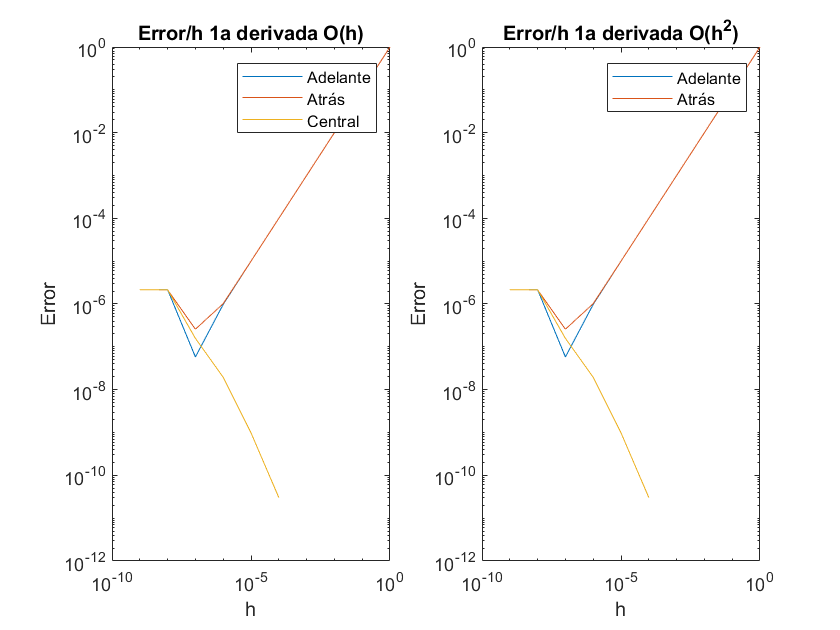

% Plot primera derivada

subplot(1,2,1)
loglog(h,error_adelante)
hold on
loglog(h,error_atras)
loglog(h,error_central)
xlabel('h')
ylabel('Error')
title('Error/h 1a derivada O(h)')
legend('Adelante','Atrás','Central')
    
%Plot segunda derivada
subplot(1,2,2)
loglog(h,error_adelante)
hold on
loglog(h,error_atras)
loglog(h,error_central)
xlabel('h')
ylabel('Error')
title('Error/h 1a derivada O(h^2)')
legend('Adelante','Atrás')

    
format short

    

**Comparación**

Para el calculo de la primera derivada usando o(h) podemos darnos cuenta que el error más chico usando la derivada de adelante y derivada hacia atras va a ser en el orden de 10^-7. Sin embargo, el error va a ser menor derivando hacia adelante, por lo que si se tiene que escoger entre derivada hacia adelanta y hacia atras, recomendamos usar más la derivada hacia adelante. Con respecto a la derivada central, nos podemos dar cuenta que esta va a ser más precisa entre más grande sea h, por lo que si se quiere derivar usando un intervalo más grande, recomendamos usar derivación central. Con respecto a o(h^2) y la segunda derivada, nos podemos dar cuenta que va a haber un menor error si usamos derivación hacia adelante y hacia atras, a diferencia de la primera derivada. Algo curioso que pasa en este caso es que entre más grande sea la h, menor error va a haber en los 3 casos de derivación, algo que no pasaba en la primera derivada. Los errores también pueden ser causados por los bits y errores de redondeo debido a que el numero puede pasar del mínimo posible. Dado que la medida de ajuste o el cálculo de la magnitud con respecto al valor teóroco o valor real que dicha magnitud tiene.